% Random seed: get same results 
rng(123)

% Data set: https://ww2.mathworks.cn/help/deeplearning/ug/data-sets-for-deep-learning.html

%The conversion of raw data to jpg/png is also on the link.


% Location of the data set, here use matlab online.
images = '/MATLAB Drive/flowerPhotos';
imds = imageDatastore(images,'IncludeSubfolders',true,'LabelSource','foldernames');

% Summarize the number of images per category.
tbl = countEachLabel(imds)

tbl = 5×2 table
      Label       Count
    __________    _____

    daisy          633 
    dandelion      898 
    roses          641 
    sunflowers     699 
    tulips         799 


% Determin the smallest amount of images in a category.
minSetCount = min(tbl{:,2})

minSetCount = 633

% Reduce the num of images to 100. This will reduce the training time.
maxNumImages = 100;
minSetCount = min(maxNumImages,minSetCount);

% Trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Each set now has exactly the same number of images.
countEachLabel(imds)

ans = 5×2 table
      Label       Count
    __________    _____

    daisy          100 
    dandelion      100 
    roses          100 
    sunflowers     100 
    tulips         100 


% Split and load the datastore
[trainImgs,valImgs,testImgs] = splitEachLabel(imds,0.8,0.1,0.1,'randomized');

% Preprocessing the datastore. inputsize = [227 227].
augImdsTrain = augmentedImageDatastore([227 227],trainImgs);
augImdsVal = augmentedImageDatastore([227 227],valImgs);
augImdsTest = augmentedImageDatastore([227 227],testImgs);

% Load pretrained network "alexnet"
net = alexnet;

% Use the |fc7| layer of AlexNet for feature extraction.
layer = 'fc7';

% Get training features with activations function.
trainingFeatures = activations(net,augImdsTrain,layer,'OutputAs','rows');

% Train a classifier, using features and labels.
classifier = fitcecoc(trainingFeatures,trainImgs.Labels);

% Get test features with activations function.
testFeatures = activations(net,augImdsTest,layer,'OutputAs','rows');

% Make a prediction by the classfier model and test features.
testPred = predict(classifier,testFeatures);

% Get the accuracy.
nnz(testPred == testImgs.Labels)/numel(testPred)

ans = 0.8200

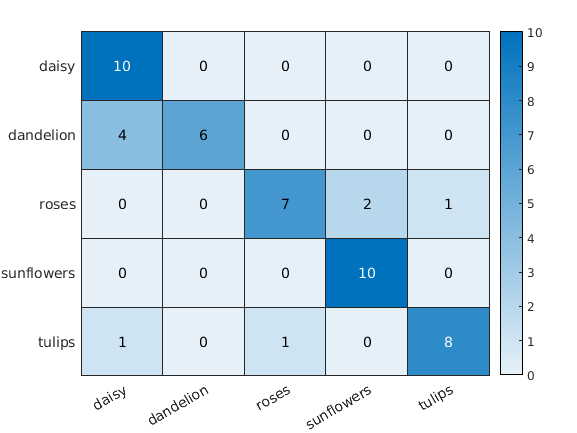

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:18 |       24.22% |       42.00% |       3.8036 |       1.3105 |      1.0000e-04 |


|      17 |          50 |       00:04:06 |      100.00% |       82.00% |       0.0009 |       0.8929 |      1.0000e-05 |


|      30 |          90 |       00:07:07 |      100.00% |       80.00% |       0.0007 |       0.9038 |      1.0000e-05 |
|======================================================================================================================|


% Get Confusion matrix.
[cmap,clabel] = confusionmat(testImgs.Labels,testPred);
heatmap(clabel,clabel,cmap)


% Show the layers of alexnet.
layers = net.Layers;

% Replace the 23th and 25th layer. 5 flowers in this set.
layers(end-2) = fullyConnectedLayer(5);
layers(end) = classificationLayer;

% Set the training Options.
options = trainingOptions('adam', ...
    'InitialLearnRate',0.0001, ...
    'Plots','training-progress', ...
    'ValidationData',augImdsVal, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',15);

% Training the network.
transferNet = trainNetwork(augImdsTrain,layers,options);

% Use the net to classify the test set.
testPred = classify(transferNet,augImdsTest);

% Accuracy.
nnz(testPred == testImgs.Labels)/numel(testImgs.Labels)

ans = 0.8600

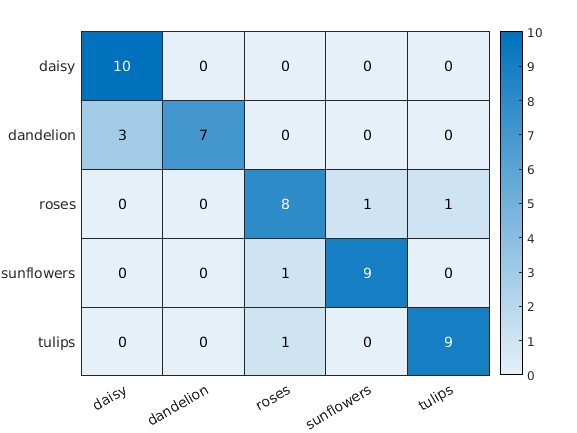

% Confusion matrix.
[cmap,clabel] = confusionmat(testImgs.Labels,testPred);
heatmap(clabel,clabel,cmap)

% List the variable in workspace
whos net

  Name      Size                Bytes  Class            Attributes

  net       1x1             245275309  SeriesNetwork              



% Accuracy = 80%.